%Exercise 1

% a causal LTI system has the system function
%determine the ROC of H(z)
% H(z) = (1 + z^-1) / ((1 + 1/4 z^-1)(1 - 1/2 z^-1))

Ts = 1;                                % sample time (choose what fits your context)

% Coefficients in powers of z^-1:
num = [1 1];                           % 1 + z^-1
den = conv([1 1/4], [1 -1/2]);         % (1 + 1/4 z^-1)(1 - 1/2 z^-1) -> [1  -0.25  -0.125]

H = tf(num, den, Ts, 'Variable','z^-1');

% Poles/zeros
z = roots(num);                        % zeros: -1
p = roots(den);                        % poles: 0.5 and -0.25
disp('Zeros:'), disp(z.')

Zeros:
    -1



disp('Poles:'), disp(p.')

Poles:
    0.5000   -0.2500




% ROC for a causal system: outside the outermost pole
roc = '|z| > 0.5';
disp(['ROC: ' roc])

ROC: |z| > 0.5


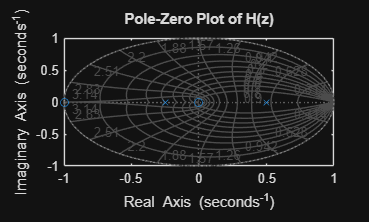


% Plot pole-zero map
figure; pzmap(H); grid on; title('Pole-Zero Plot of H(z)')